**Weight Loss dataset**

This data was collected from a crowd-sourced experiment looking at the effects of various parameters on weight loss. Data was gathered either through the use of self-tracking apps (such as activity trackers like FitBit (TM)) or through questionnaires. The study lasted 3 months and the values presented here have been aggregated and patients with missing data have been dropped along with any potentially identifiable information. Our overall goal is to find which parameters are most associated with weight loss.

**Data Description:** The data is given in a sqlite database named **weightdata.sqlite**, with a single table, **patient**. * age: Patient's age at the start of the study. * gender: Self-identified gender. * height: The patient's height (in inches). * initweight: The weight of the patient at the start of the study (in pounds). * calintake: The average number of calories consumed per day. * jobstatus: The self-identified job status, either Active or Inactive. * timecardio: The average minutes of cardio (per week). * timeresist: The average minutes of resistance training (per week). * sleep: The average amount of sleep (hours) per day. * steps: The average number of steps per day (counted using phone accelerometers). * deltaweight: The change in weight after the 3-month study (in pounds).

**Variable names**

- data: All patient data, represented as a Matlab table object

**Objectives:**

- Understand the dataset

- Be able to manipulate the database tables in the DB Browser for SQlite

- Connection to the database using Matlab functions, native connection, and JDBC

- Use SQL query in Matlab, import data to a cell array, convert a cell array to a table, and convert to a cell array to a matrix

- Be able to manipulate the data in a cell array, table, and matrix

- Logical index array

- Corrcoef function corrcoef() [https://www.mathworks.com/help/matlab/ref/corrcoef.html#bunkanr](https://www.mathworks.com/help/matlab/ref/corrcoef.html#bunkanr)

- Two-sample t-test - MATLAB ttest2 [`[h,p,ci,stats] = ttest2(``___``)`](https://www.mathworks.com/help/stats/ttest2.html#d117e865369)

- Combine variables to test a new model

- Multivariate linear regression, mvregress() 

- Z-scaling

# Connect to the database

dbfile = fullfile(pwd,'weightdata.sqlite');

Invalid expression. Check for missing or extra characters.

conn = sqlite(dbfile)

## Data Statistics using SQL

Use SQL queries to answer each of the following questions.

% establish sqlquery of 'SELECT * FROM patient'
% use fetch to import data to dbdata
% use cell2table() to convert the cell arry dbdata to a table as data assigning the following column names (VariableNames).
% 'id' 'age' 'gender' 'height' 'initweight' 'calintake' 'jobstatus' 'timecardio' 'timeresist' 'sleep' 'steps' 'deltaweight'
sqlquery=?
dbdata = fetch(?)

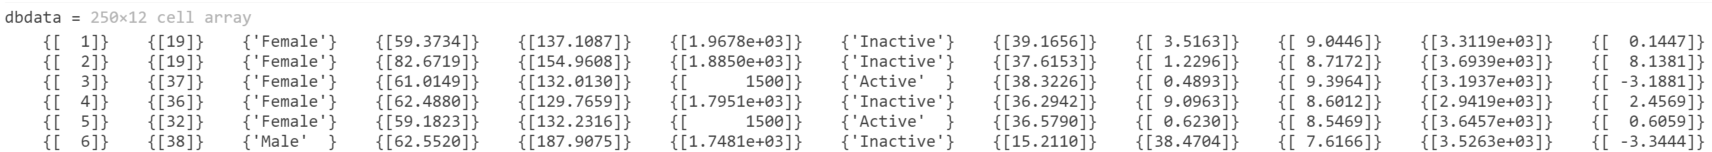

data = cell2table (?)

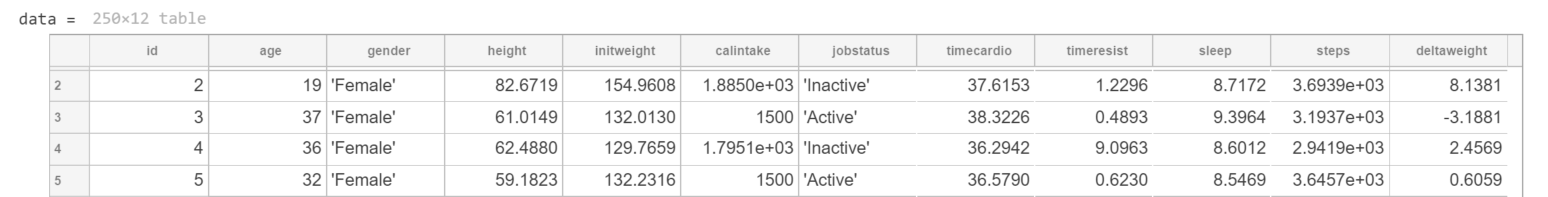

% print data.age

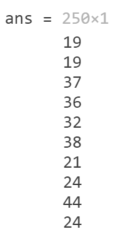

# Active versus Inactive jobstatus and average age differences between active and inactive

## How many patients have "Active" jobstatus, and how many are "Inactive"? 


% perform sqlquery 'SELECT * FROM patient WHERE ? , fetch data and use numel count how many pateints are active
sqlquery=?
num_active_job = numel(?);

% Do the same  and answer how many patients have "Inactive" jobstatuses. 

sqlquery=?
num_inactive_job = numel(?);


# **Average Age of Patients with Active and Inactive jobstatus**

**What is the average age of the patients with Active (and Inactive) job status? **


% perform sqlquery select only the age column or active and inactive,  fetch data, convert the cell array to a matrix and calculate the mean of the age
sqlquery1 = ? % select age column for active
all_active_age = fetch (?);
mean (?) % convert the cell array to a matrix and calculate the mean of the age
sqlquery = ? % select the age column for inactive
all_inactive_age = fetch(?);
mean (?) % convert the cell array to a matrix and calculate the mean of the age
% Can you calculate the mean directly from the cell array or convert it to a table? 



# Gender-specific differences in exercise preference.

Use the data to answer whether there are gender-specific differences in exercise preference (resistance vs cardio) and whether the subject does ANY exercise. Remember to not include patients with missing exercise information in the analysis.

% This creates a logical index variable no_exercise, which stores patients' data that do
% not do exercise, meaning they spend no time doing cardio or resistance
% training (data.timecardio and data.timeresist).
no_exercise= data.timecardio==0?data.timeresist==0?; 
% This creates a figure named gender.
figure 
% Creates a scatter plot for patients with exercise (~no_exercise) separating male and female with different colors.
gscatter( data.timecardio(~no_exercise), data.timeresist(~no_exercise),)
% This titles the scatter plot.
title ('Minimum Resistance versus Minimum Cardio for Gender Difference')
% This labels the x axis.
xlabel('Minimum Cardio Time')
% This labels the y axis.
ylabel('Minimum Resistance Time')

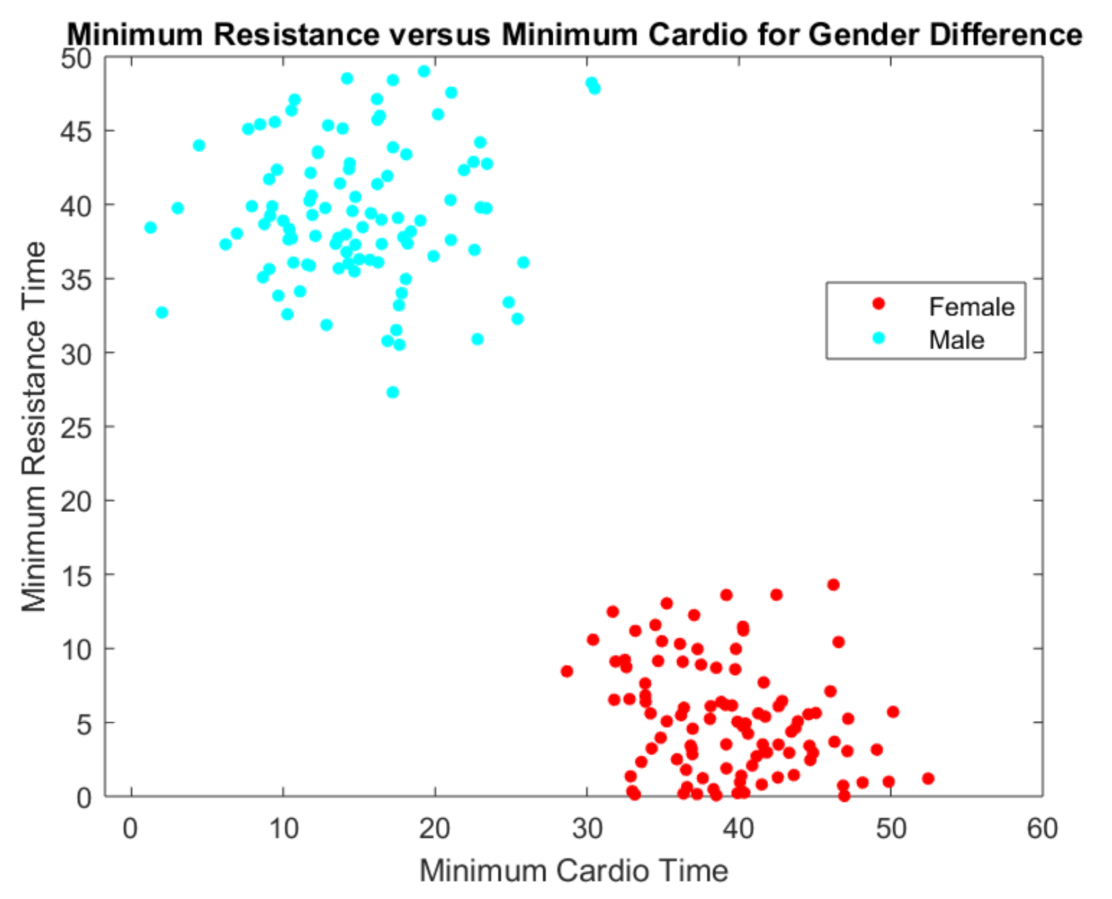

## Gender Figure Caption

## Gender Figure Conclusion

# Differences between job status.

Use the data (box plots) to answer whether the job-status influences the average number of steps a subject takes per day and the average number of calories consumed. Does jobstatus affect the initial weight? 

% This creates a figure named jobstatus. 

% Creates subplots, 1 row by 3 columns. 
% This creates a boxplot with steps versus job status aa the leftmost figure
subplot(?)
boxplot(?);
% This labels the y axis.
ylabel('Steps')

% This creates a boxplot with calorie intake versus job status in the middle.
subplot(?)

boxplot(?);
% This labels the y axis.
ylabel('Intake Calories')

% This figure is on the right of the subplot. 
subplot(?)
% This creates a boxplot with inital weight versus job status. 
boxplot(?);
% This labels the y axis.
ylabel('Initial Weight')
hold off

## Jobstatus Figure Caption

## Jobstatus Figure Conclusions

# Effects of sleep.

Plenty of research has shown that sleep is important for weight loss. Use this data to explore this question. Is it correlated with the weight change? Is it different between genders or job types (active or inactive)? Is it correlated with anything else in the dataset?

## Which variables are significantly correlated with sleep, and why?  using corrcoef()

% This uses Matlab's built-in corrcoef function which determines if any
% variable is correlated with a weight change. 
% [R,C] = corrcoef([data.sleep, data.age, data.height, data.initweight, ...
%    data.deltaweight, data.calintake, data.timecardio, data.timeresist, ...
%    data.steps]);
% Change the data type of data.age to double before calling the corrcoef()

data.age=double(data.age);
[R,C] = corrcoef([data.sleep, data.age, data.height, data.initweight, data.deltaweight, data.calintake, data.timecardio, data.timeresist, data.steps]);

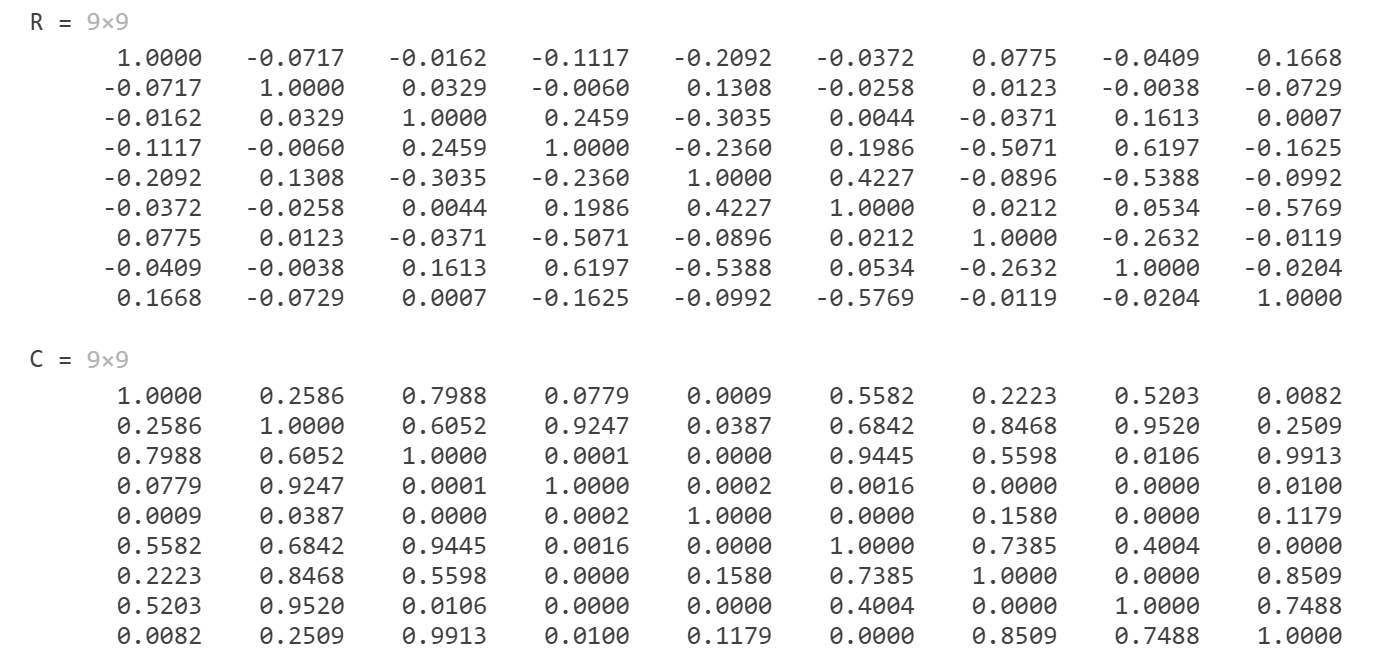

[R,P] = corrcoef()

The diagonal entries of R are set to one by convention, while the off-diagonal entries are correlation coefficients of variable pairs. The values of the coefficients R can range from -1 to 1, with -1 representing a direct, negative correlation, 0 representing no correlation, and 1 representing a direct, positive correlation. `R` is symmetric. 

P-values, returned as a matrix. `P` is symmetric and is the same size as `R`. The diagonal entries are all ones and the off-diagonal entries are the p-values for each variable pair. P-values range from 0 to 1, where values close to 0 correspond to a significant correlation in `R` and a low probability of observing the null hypothesis.

% This calculates the significance value. 
% Variables are significant if the P value is less than 0.01.
h = C(1,:) < 0.01; 
% Based on the significance, print out which variables are significantly correlated with sleep, and why?
disp/fprintf????

% This calculates the R^2 value. 
R2 = R(1,:).^2; % predict percentage of effects

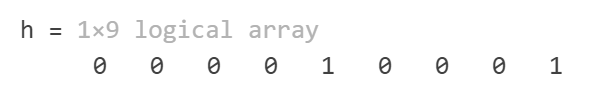

## Does the job status affect sleep and why?  Does gender  have different sleep patterns?  using ttest2()

% This uses Matlab's built-in strcmp function to test the correlation of
% strings. This specific example focuses on the jobstatus variable.
active = strcmp(data.jobstatus,'Active');

% ttest2 of sleep between active and inactive
% data. The alpha value is set to 0.01.
[P,~,ci] = ttest2(?, 'alpha', 0.01);

% does the job status affect sleep and why?  print out your answer and arguments

% This uses Matlab's built-in strcmp function to test the correlation of
% strings. This specific example focuses on the gender variable.
male_mask = strcmp(?);

% This uses Matlab's built-in ttest2 function which completed a ttest on the
% data between male and female. The alpha value is set to 0.01.

[P, ~, ci] = ttest2(?);
% does gender affect sleep and why?  print out your answer and arguments



## **A scatter plot between the sleep and the  deltaweight variable.   A scatter plot between the sleep and the steps variable.**

% A scatter plot between the sleep and the  deltaweight variable.

% This uses the polyfit tool to find an equation for the best fitting line
% between the sleep and the deltaweight variable.

res = polyfit(?);


% A scatter plot between the sleep and the steps variable.
% This uses the polyfit tool to find an equation for the best fitting line
% between the sleep and the steps variable.
res1 = polyfit(?);

% This creates a figured called sleep.
figure
?????

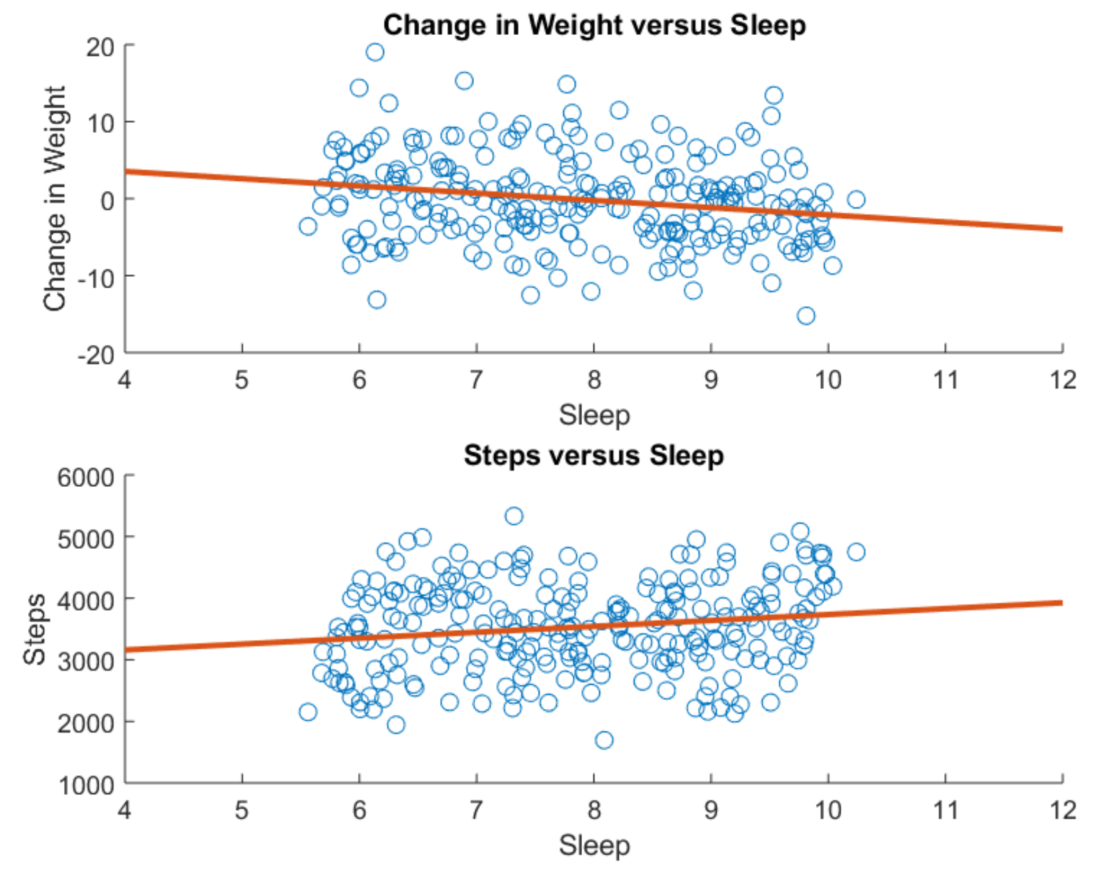

## Sleep Figure Caption

## Conclusions:

## Combining values to calculate net calories and plot net calories vs.  weight loss.

We talked previously about inter-correlations between features when building linear models. We know that gender has effects on exercise preference and jobtype affects the number of steps. One way to alleviate those issues is to use domain knowledge to create summary values. We know from biology that what's really important for weight loss is creating a calorie deficit. We know from the data how many calories they consumed but not how much they expended.

Basal calarie and exsecise calarie. 

basal -> calories burned when not active

execise -> calories bured during active peroid

% Google around and find an equation for calculating the Basal Metabolic
% Rate (BMR) as a function of parameters that we measured. 

% BMR calculation for men (metric) BMR = 66.47 + ( 13.75 x weight in kg ) +
% ( 5.003 x height in cm ) - ( 6.755 x age in years ) 

% BMR calculation for women (metric) BMR = 655.1 + ( 9.563 x weight in kg ) 
% + ( 1.850 x height in cm ) - ( 4.676 x age in years )

% Reference: Harris JA, Benedict FG. A biometric study of human basal 
% metabolism. Proc Natl Acad Sci USA 1918;4(12):370-3. 
% Website: http://www.globalrph.com/harris-benedict-equation.htm


basalcalories = [655 + (4.35*data.initweight) + (4.7*data.height) - (4.7*data.age)];
malebasalcalories = [66 + (6.23*data.initweight) + (12.7*data.height) - (6.8*data.age)];

basalcalories(male_mask == 1) = malebasalcalories(male_mask == 1);

% Google around and find estimates of the amount of calories burned
% during aerobic excercise and resistence excercise. includ a reference 

% ? calories for resistance training ( I am using 533)
% ? calories for high impact aerobics  ( I am using 365)
% Reference: 


% Average weight determined to use for calories expended during exercise
avgweight = mean(data.initweight);
% This divides 533 calories for cardio by 60 minutes per hour.
caloriescardio = data.timecardio*(?/60);
% This divides 365 calories for resistance training by 60 minutes per hour.
caloriesresistance = data.timeresist*(?/60);
% This totals cardio calories and resistance calories by adding the two
% variables.
exercisecalories = caloriescardio + caloriesresistance;

% Now use these two values (and one from the dataset) to estimate the
% net calorie change.

% This estimates the net calorie change. Calorie intake minus the calories
% lost to exercise minus the calories lost to BMR is the net calorie
% change (data.calintake - exercisecalories - basalcalories)
netcalories = ?;

% How well does this "netcalories" correlate with the change in weight?  
% We will use gscatter plot to answer the question.
gscatter(?)
% This uses the polyfit tool to find an equation for the best fitting line
% between the net calories and change in weight variable(data.deltaweight).

polyfit(?)

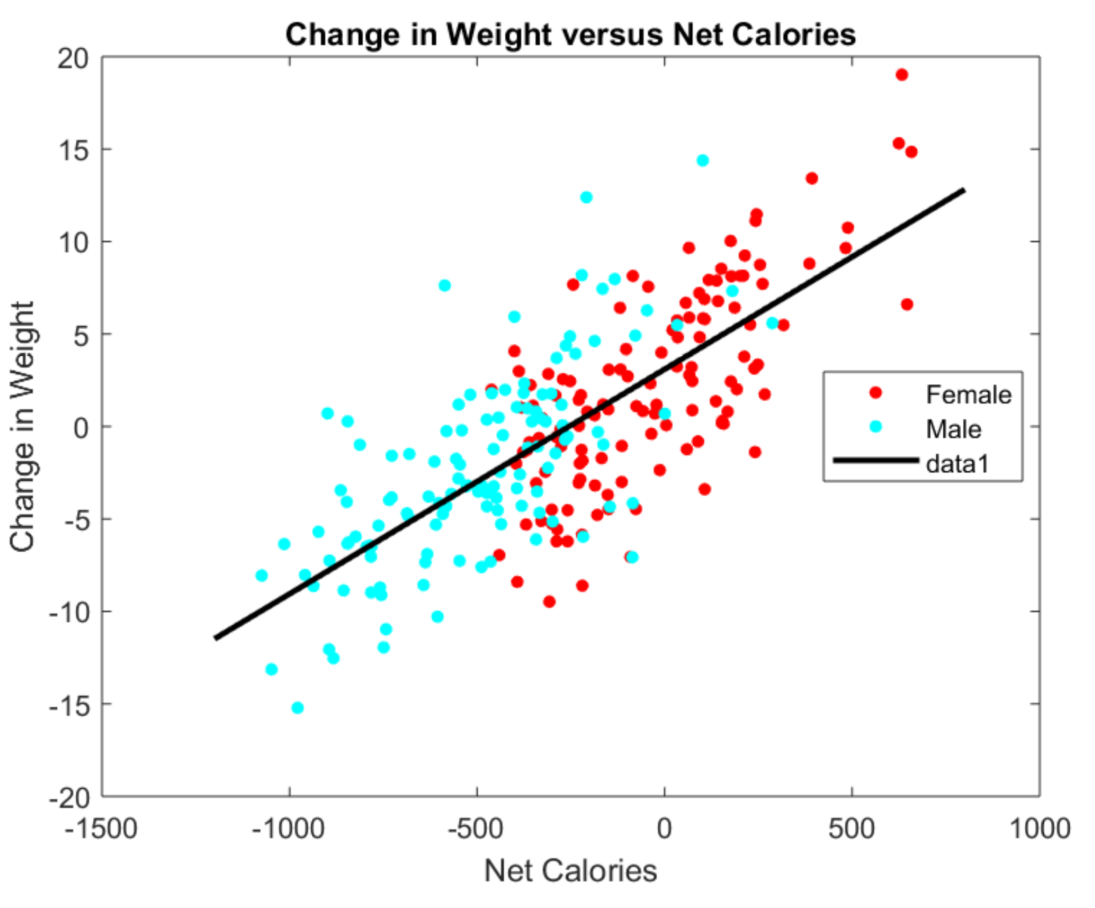

## Basal Figure Caption

## Conclusions

# Build a model

Use all of this information to build the best model to predict the change in weight for each subject. Plot your predictions versus reality. Calculate the R^2 and discuss what it implies. Discuss the effect sizes that you calculate and their relevance to weight loss.

## Practice corrcoef and ttest2

% This uses Matlab's built-in corrcoef function which determines if any
% variable is correlated with a change in weight. 
[RR,CC] = corrcoef([data.deltaweight, netcalories, data.sleep,data.steps]);


% This calculates the significance value. Variables are significant if the
% P value is less than 0.01. which variable is highly correlated with the deltaweight? 
h = CC(1,:)<0.01;

% please  calculate the R^2 value. which variable predicts the highest percentage of effects.
R2 = ?


% This uses Matlab's built-in ttest2 function which completed a ttest on the
% data. The alpha value is set to 0.01. Does the job status affect the weight loss?
[PP, ~, cci] = ttest2(data.deltaweight(active), data.deltaweight(~active),...
     'alpha', 0.01);
 
% This uses Matlab's built-in ttest2 function which completed a ttest on the
% data. The alpha value is set to 0.01.  Does the gender affect the weight loss?
[PP, ~, cci1] = ttest2(data.deltaweight(male_mask),...
     data.deltaweight(~male_mask), 'alpha', 0.01);
 



## **Multivariate** normal regression

`mvregress(`[`X`](https://www.mathworks.com/help/stats/mvregress.html?searchHighlight=mvregress&s_tid=doc_srchtitle#btkqm0f-X)`,`[`Y`](https://www.mathworks.com/help/stats/mvregress.html?searchHighlight=mvregress&s_tid=doc_srchtitle#btkqm0f-Y)`)` returns the estimated coefficients for a [multivariate normal regression](https://www.mathworks.com/help/stats/mvregress.html#btkr6ds-3) of the *d*-dimensional responses in `Y` on the design matrices in `X`.

% This initializes the x variable to have 4 columns. The first column is
% the net calories. The second column is the sleep variable. The third
% column is the inactive job status and the fourth column is just ones (the
% size of the sleep variable).
x = [netcalories, data.sleep, ~active, ones(size(data.sleep))];
% This initializes the y variable to be the change in weight.
y = data.deltaweight;
     
     
% This uses Matlab's built-in function mvregress which completes linear
% regression on the data.
linearregression = mvregress(x,y);
% The prediction is the x variable multiplied by the linearregression
% test variable. 
ypred = ?;


figure
% This creates a scatter plot between y and ypred.
????

% This adds a trendline

trend=polyfit(?)

% Discuss the effect sizes that you calculate and their relevance to weight loss.


% This uses Matlab's built-in corrcoef function which determines if y and ypred
% is correlated (y, ypred). Is this correlation significant at 99% level?
[R1,P1] = ?



% This finds the R^2 value. And how much does it predict the combined effects? 
R3 = R1(1,:).^2;



## Model Figure Caption

## Conclusions